## Demo of Matlab plotting, logical expressions, and histograms using the SIO Pier Temperature time series

Used in this demo: load, display, sprintf, plot, xlabel, ylabel, title, clf, figure, set, gca, datevec, ==, &, |, >=, <=, legend, hold, xtickformat, histogram, subplot

clear
close all
load SIO_TEMP_1917_2025.mat
whos

  Name            Size             Bytes  Class       Attributes

  T           39751x1             318008  double                
  readme          1x70               140  char                  
  time        39751x1             318008  datetime              



## Display first, second, and last time values

time(1:2)

ans = 2×1 datetime array
   01-Jan-1917
   02-Jan-1917


time(end)

ans = datetime
   31-Oct-2025


formatspec = 'time(1) is %s';
display(sprintf(formatspec,time(1)))

time(1) is 01-Jan-1917


formatspec = 'time(end) is  %s';
display(sprintf(formatspec,time(end)))

time(end) is  31-Oct-2025


## Display first 10 T values

1:10

ans =      1     2     3     4     5     6     7     8     9    10


T(1:10)

ans =    11.5000
   11.5000
   11.9000
   11.5000
   11.7000
   11.9000
   12.0333
   12.1667
   12.3000
   12.2000


## Display every other value of first 10 values

1:2:10

ans =      1     3     5     7     9


T(1:2:10)

ans =    11.5000
   11.9000
   11.7000
   12.0333
   12.3000


## Plot a time series of surface temperature

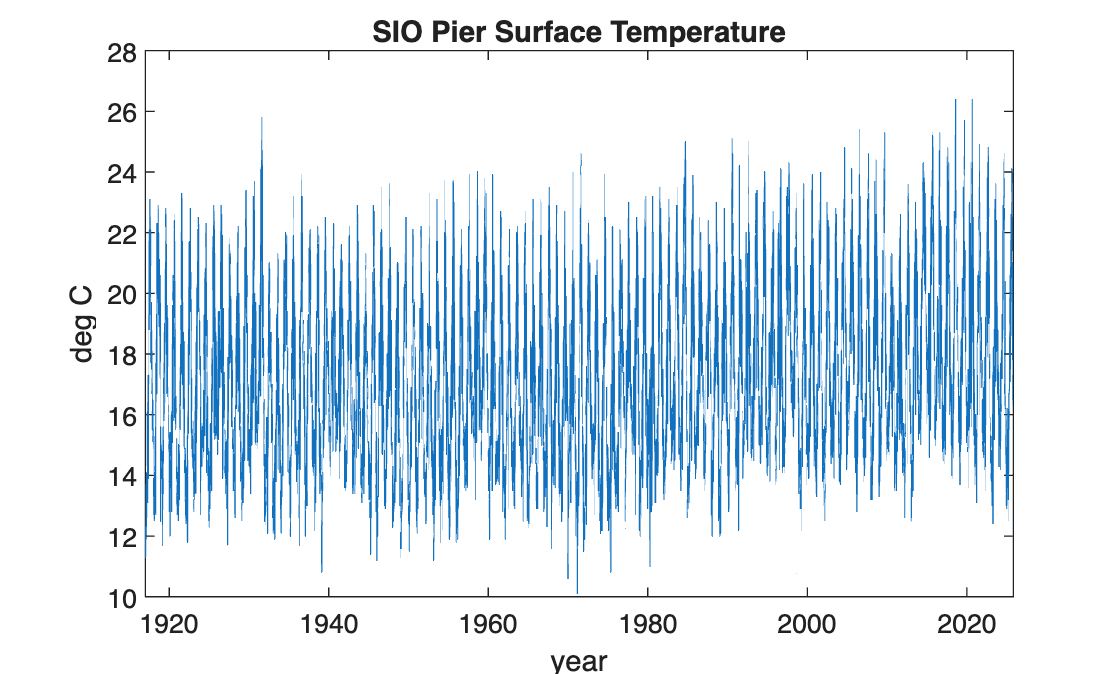

figure (1)
clf
plot(time,T)
ylabel('deg C')
xlabel('year')
title('SIO Pier Surface Temperature')

## Get the year, month, and day for each data point using datevec.m, plot year vs time

figure (2)
clf
[yr,mo,dy] = datevec(time);
yr(1), mo(1), dy(1)

ans = 1917

ans = 1

ans = 1

yr(end),mo(end),dy(end)

ans = 2025

ans = 10

ans = 31

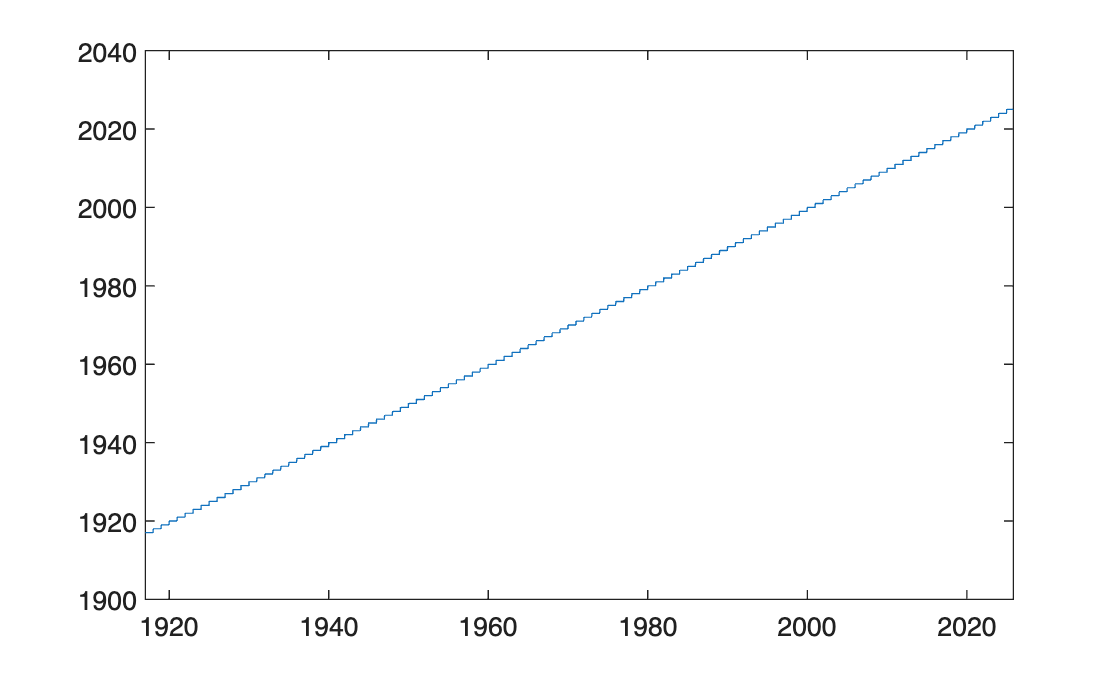

plot(time,yr)

## What is a logical expression in MATLAB?

MATLAB represents Boolean data using the logical data type, which represents true and false states using the numbers 1 and 0 , respectively.  Logical arrays are returned by the logical operators (& "and", | "or", ~ "not") and the relational operators (==,~=,<,<=,>=,>), as well as by functions like ANY, ALL, ISNAN, ISINF, ISFINITE, ISEMPTY, ISEQUAL, etc.

x = 1:10

x =      1     2     3     4     5     6     7     8     9    10


x>5

ans = 1×10 logical array
   0   0   0   0   0   1   1   1   1   1


x(x>5)

ans =      6     7     8     9    10


x==3

ans = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


x(x==3)

ans = 3

x<4

ans = 1×10 logical array
   1   1   1   0   0   0   0   0   0   0


x(x<4)

ans =      1     2     3


x>5 & x<=7

ans = 1×10 logical array
   0   0   0   0   0   1   1   0   0   0


x(x>5 & x<=7)

ans =      6     7


x==4 | x >=8

ans = 1×10 logical array
   0   0   0   1   0   0   0   1   1   1


x(x==4 | x >=8)

ans =      4     8     9    10


## Plot surface temperature for year 2018

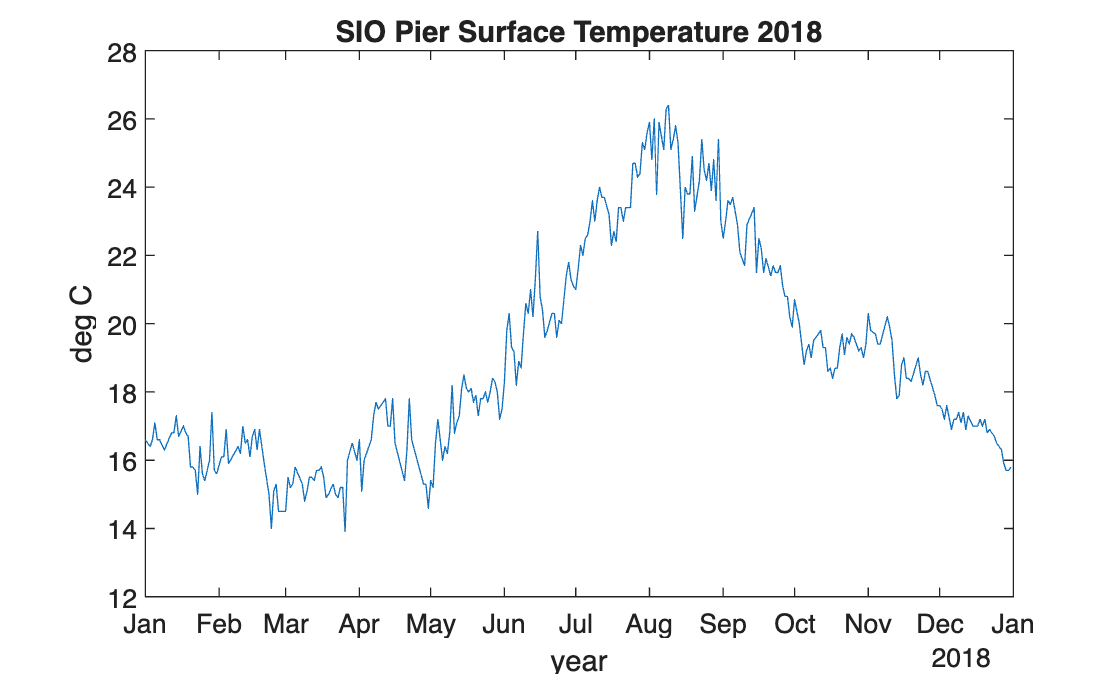

figure (3)
clf
plot(time(yr==2018),T(yr==2018))
ylabel('deg C')
title('SIO Pier Surface Temperature 2018')
xlabel('year')

## Plot year 2018 using xlim

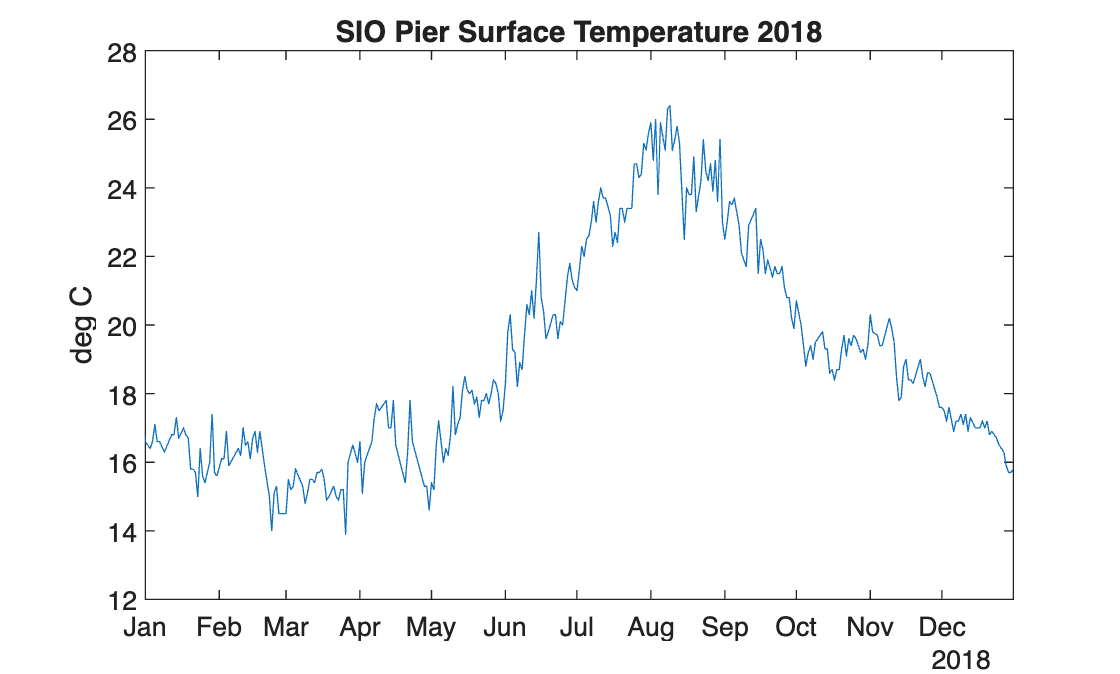

figure (4)
clf
plot(time,T)
xlim([datetime(2018,1,1) datetime(2018,12,31)])
ylabel('deg C')
title('SIO Pier Surface Temperature 2018')

## Plot  August  2018

figure (5)
clf


## Plot July-September 2018

figure (6)
clf


## Plot temperature from 2010 to 2022

figure (7)
clf


## Plot two time series on the same plot -  2010 and 2018

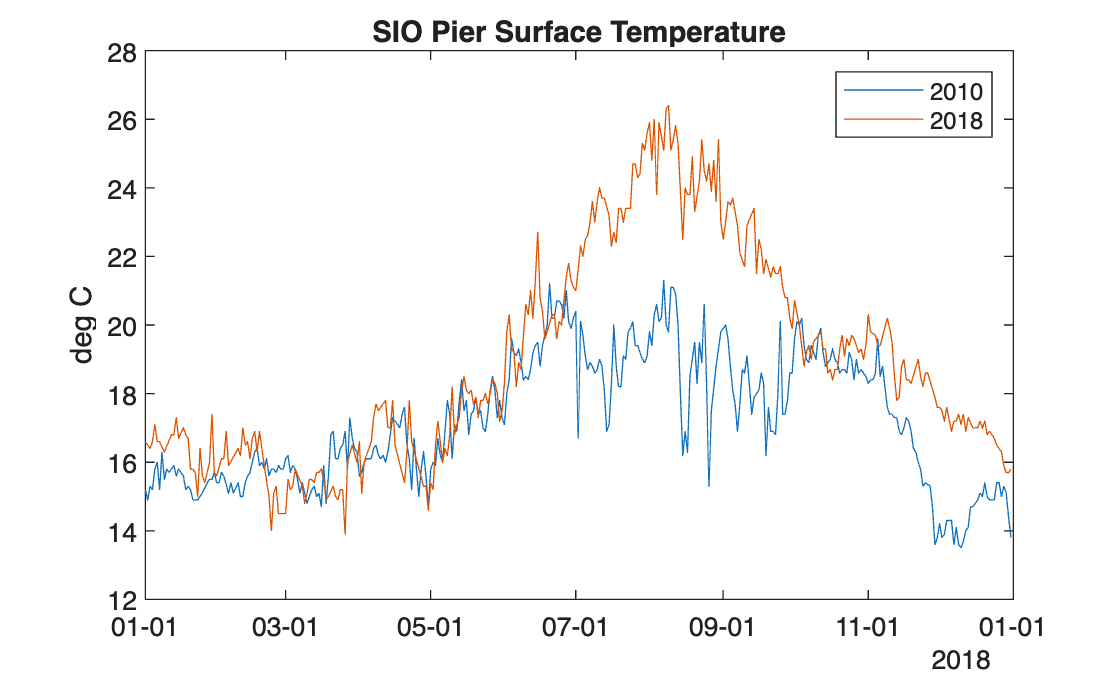

figure (8)
clf
plot(time(yr==2018),T(yr==2010))
hold on
plot(time(yr==2018),T(yr==2018))
xtickformat("MM-dd")
ylabel('deg C')
title('SIO Pier Surface Temperature')
legend('2010','2018')

## Indicate max and min values using symbols

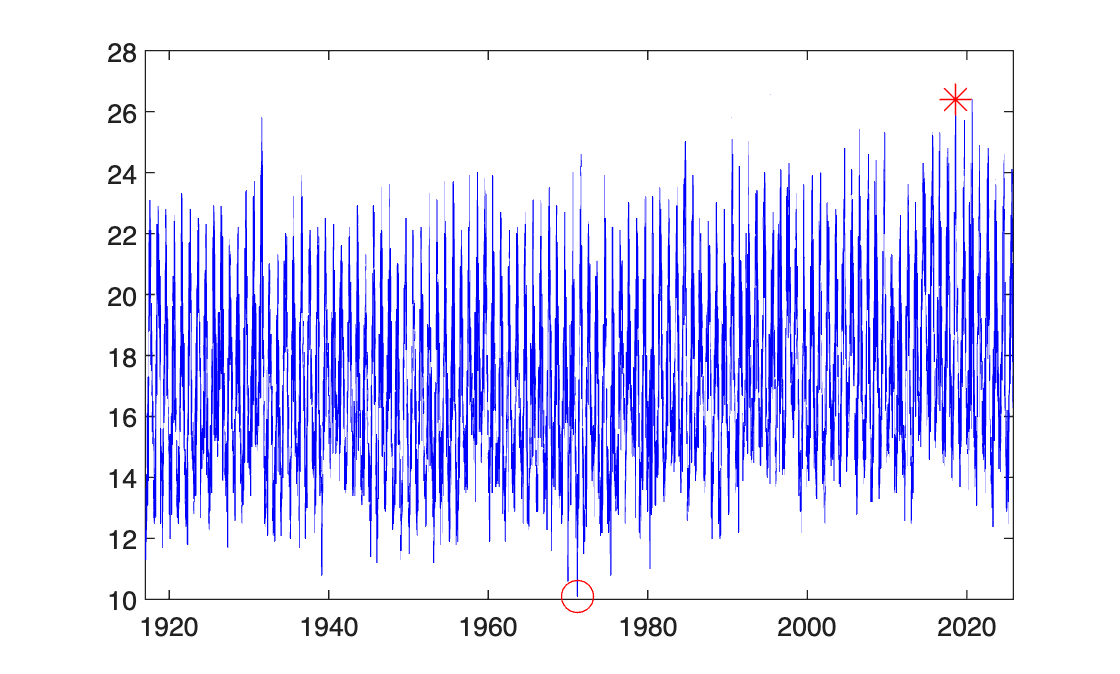

figure (9)
clf
plot(time,T,'b')
[Tmax,ind_Tmax] = max(T);
hold on
plot(time(ind_Tmax),Tmax,'r*','MarkerSize',12)
[Tmin,ind_Tmin] = min(T);
plot(time(ind_Tmin),Tmin,'ro','MarkerSize',12)
hold off

formatspec = 'Max Temperature is %.2fC, %s';
display(sprintf(formatspec,Tmax,time(ind_Tmax)))

Max Temperature is 26.40C, 09-Aug-2018


formatspec = 'Min Temperature is %.2fC, %s';
display(sprintf(formatspec,Tmin,time(ind_Tmin)))

Min Temperature is 10.10C, 02-Mar-1971


## Histogram of pier temperature, bin width = 1°C

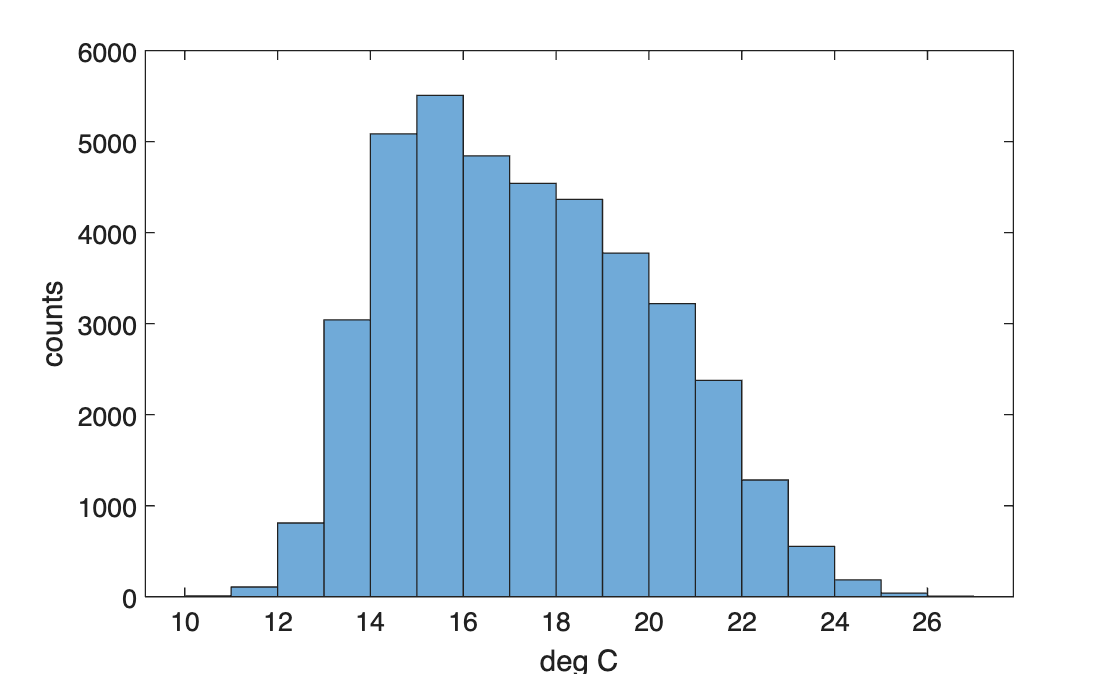

figure (10)
clf
histogram(T,'BinWidth',1)
ylabel('counts')
xlabel('deg C')

## Histogram of pier temperature, bin width = 0.5°C

figure (11)
clf

## Plot histogram with probability vs PDF normalization using 0.5° and 1°C bins

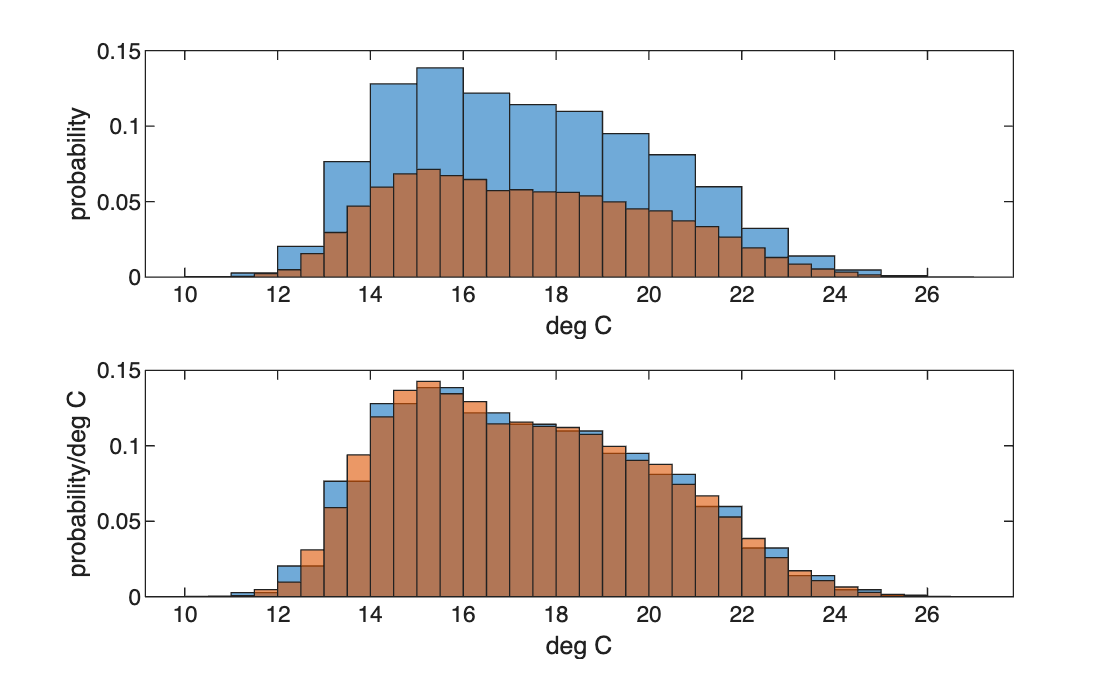

figure (12)
clf
subplot(2,1,1)
histogram(T,'Normalization','probability','BinWidth',1)
ylabel('probability')
xlabel('deg C')
hold on
histogram(T,'Normalization','probability','BinWidth',0.5)
ylabel('probability')
xlabel('deg C')
subplot(2,1,2)
histogram(T,'Normalization','pdf','BinWidth',1)
ylabel('probability/deg C')
xlabel('deg C')
hold on
histogram(T,'Normalization','pdf','BinWidth',0.5)
ylabel('probability/deg C')
xlabel('deg C')

## Plot histograms (with PDF normalization) of Feb temperature overplotted with Aug temperature 

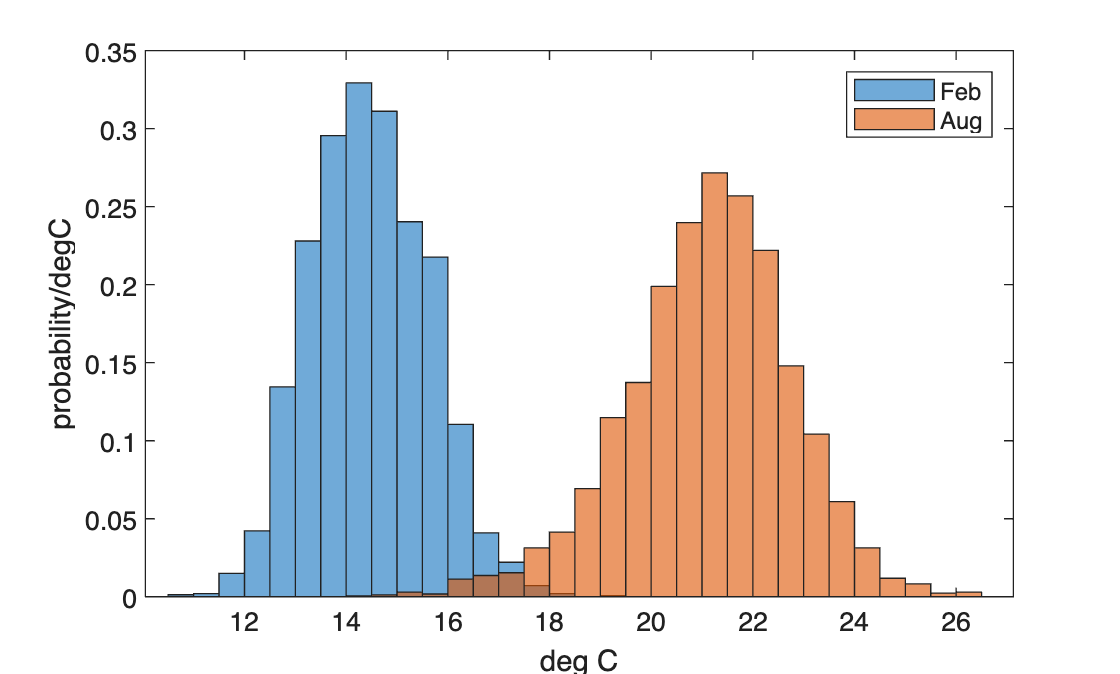

figure (13)
clf
histogram(T(mo==2),'Normalization','pdf','BinWidth',0.5)
hold on
histogram(T(mo==8),'Normalization','pdf','BinWidth',0.5)
legend('Feb','Aug')
xlabel('deg C')
ylabel('probability/degC')

## Plot histograms (with PDF normalization) of 4 seasons (JFM, AMJ, JAS, OND)

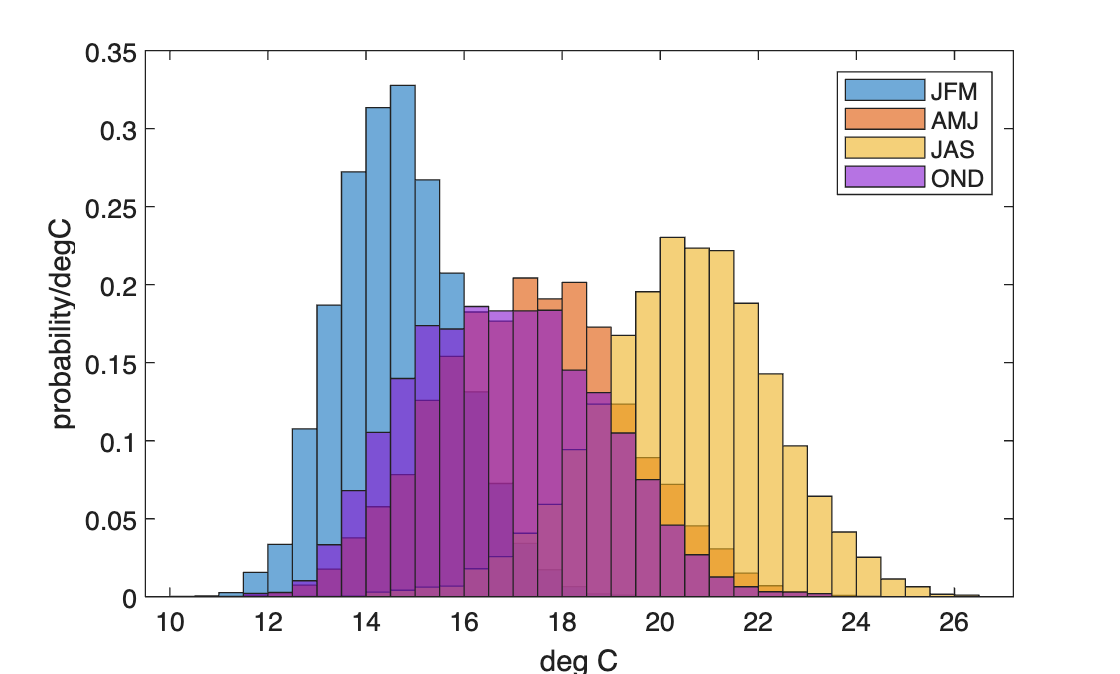

figure (14)
clf
histogram(T(mo>=1 & mo <=3),'Normalization','pdf','BinWidth',0.5)
hold on
histogram(T(mo==4 | mo==5 | mo==6),'Normalization','pdf','BinWidth',0.5)
histogram(T(mo>=7 & mo <=9),'Normalization','pdf','BinWidth',0.5)
histogram(T(mo>=10 & mo <=12),'Normalization','pdf','BinWidth',0.5)
legend('JFM','AMJ','JAS','OND')
xlabel('deg C')
ylabel('probability/degC')